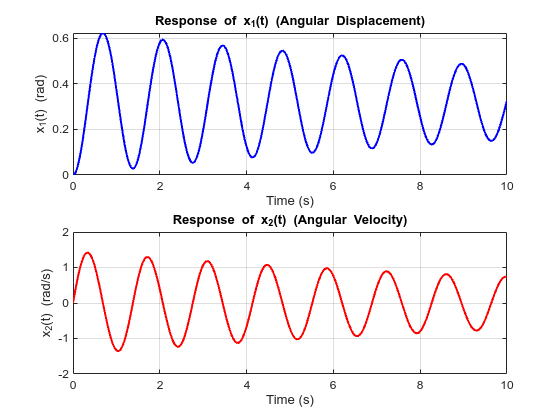

% Define the system parameters
a0 = 22.073;    % Parameter a0
a1 = 0.135;     % Parameter a1
b0 = 30;        % Parameter b0

% Define the equilibrium control input
u_eq = 0.2273;  % Equilibrium control input in Nm

% Define the time span for the simulation
t_span = [0 10]; % Simulate from t = 0 to t = 10 seconds

% Define the initial conditions
x0 = [0; 0]; % Initial state [x1(0) = 0, x2(0) = 0]

% Define the nonlinear state-space model
nonlinear_model = @(t, x) [x(2); 
                           -a0*sin(x(1)) - a1*x(2) + b0*u_eq];

% Simulate the system using ode45
[t, x] = ode45(nonlinear_model, t_span, x0);

% Plot the results
figure;
subplot(2,1,1);
plot(t, x(:,1), 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('x_1(t) (rad)');
title('Response of x_1(t) (Angular Displacement)');
grid on;

subplot(2,1,2);
plot(t, x(:,2), 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('x_2(t) (rad/s)');
title('Response of x_2(t) (Angular Velocity)');
grid on;


% Display the equilibrium values at the end of simulation
x1_final = x(end,1);
x2_final = x(end,2);

fprintf('The value of x_1 at steady state is %.4f rad.\n', x1_final);

The value of x_1 at steady state is 0.3278 rad.


fprintf('The value of x_2 at steady state is %.4f rad/s.\n', x2_final);

The value of x_2 at steady state is 0.7376 rad/s.
